% define max and min 
%   max_alpha = 0.35
%   min_alpha = 0.15
%   max_A = 1.5
%   min_A = 0.5 
% Draw random number between min and max 
%   (max_alpha-min_alpha)*rand() + min_alpha
%   (max_A-min_A)*rand() + min_A
alpha = 0.3129

alpha = 0.3129

A = 1.4058

A = 1.4058

Find optimal capital borrowing choice 

clear all;
alpha=0.3129;
A=1.4058;
r=1.05;
p=1;
L=2;
choice_grid_count=100;
capital_grid=linspace(0, 1,choice_grid_count);
profit_at_capitalgrid=p*A*(capital_grid.^alpha)*(L^0.5)-(r*capital_grid);
[max_profit, max_profit_index]=max(profit_at_capitalgrid);
max_profit

max_profit = 1.0763

max_profit = 1.0763

max_profit_index

max_profit_index = 47

max_profit_index = 47

optimal_capital_choice = capital_grid(max_profit_index);

optimal_capital_choice = 0.46465 

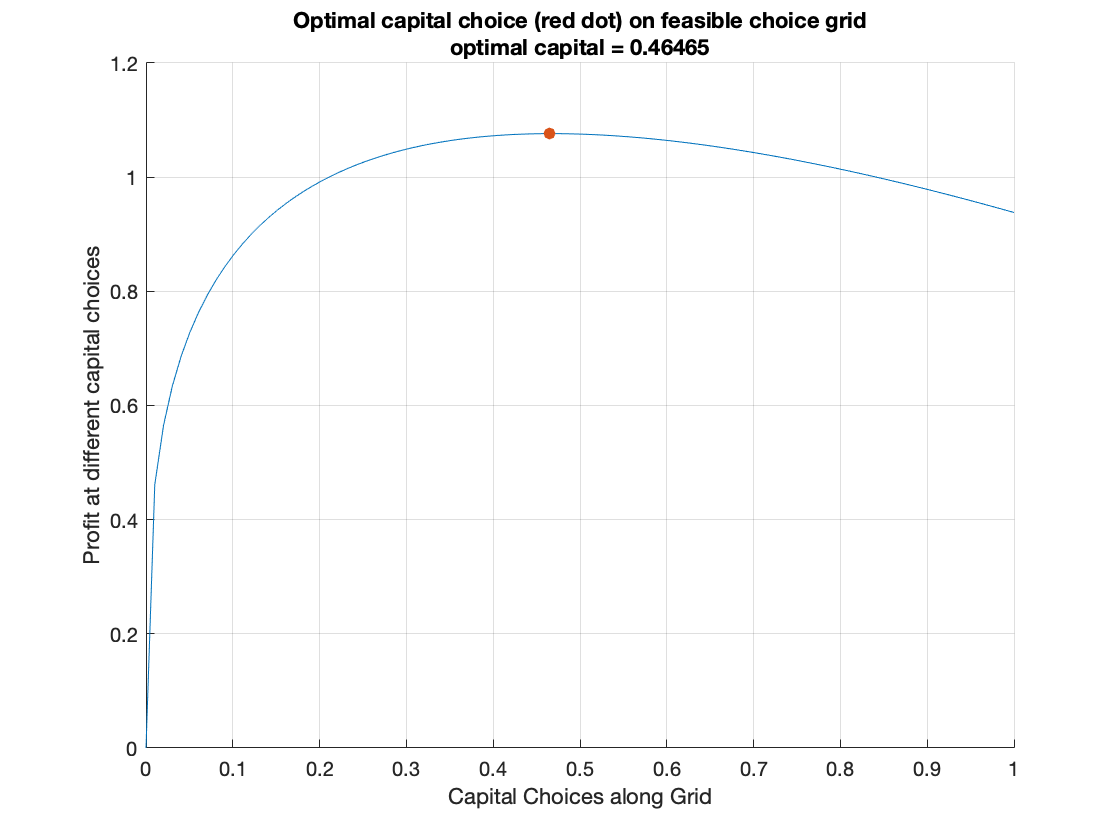

figure();
hold on;
plot(capital_grid, profit_at_capitalgrid);
scatter(optimal_capital_choice, max_profit, 'filled');
xlabel('Capital Choices along Grid');
ylabel('Profit at different capital choices');
title({'Optimal capital choice (red dot) on feasible choice grid';...
 ['optimal capital = ', num2str(optimal_capital_choice)]});
grid on;

4.) write model in matlab using symbolic toolbox 

% define the symbols 
syms r p alpha L K A 
% Define profit function
fpi = p*A*K^(alpha)*L^0.5 - r*K 

$$fpi = A\,K^{\alpha }\,\sqrt{L}\,p-K\,r$$

%Take derivative of fpi with respect to K 
dPIdK = diff(fpi, K)

$$dPIdK = A\,K^{\alpha -1}\,\sqrt{L}\,\alpha \,p-r$$

% solve where deerivative equals 0
KOpti = solve(dPIdK == 0, K, 'REAL',true)

$$KOpti = {\left(\frac{r}{A\,\sqrt{L}\,\alpha \,p}\right)}^{\frac{1}{\alpha -1}}$$

**3.3 Demand Curve of Credit **

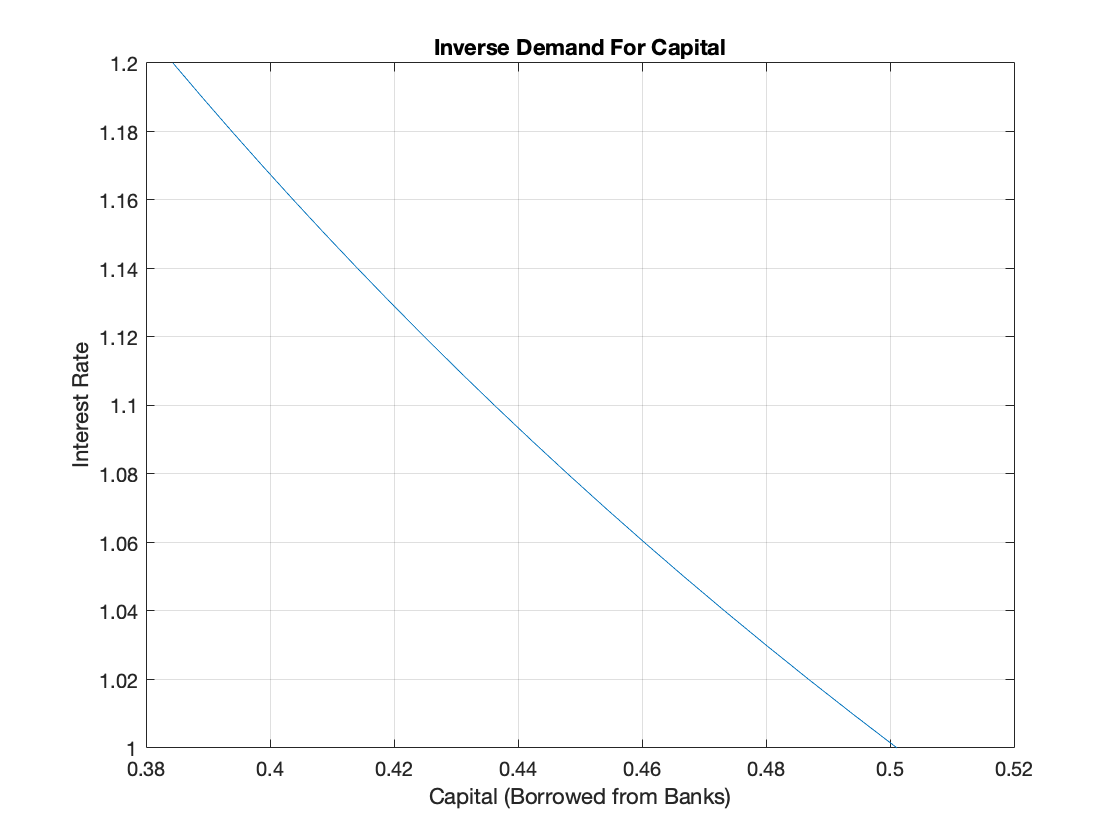

p=1; 
L=2; 
A=1.4058; 
alpha=0.3129; 
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Inverse Demand For Capital'});
grid on;

3.)

% Type 1 fraction 
%   frac_t1 = rand()
% Type 2 fraction
%   frac_t2 = (1-frac_t1)*rand()
% Type 3 fraction
%   frac_t3 = (1-frac_t1-frac_t2)*rand()
% Type 4 fraction
%   frac_t4 = 1-frac_t1-frac_t2-frac_t3

t1 = 0.1270

t1 = 0.1270

t2 = 0.7974

t2 = 0.7974

t3 = 0.0478

t3 = 0.0478

t4 = 0.0278

t4 = 0.0278

keep p=1 and L=2. We are given values of the exogenous variables (A and alpha) for each Type 

Demand curve for Type 1 

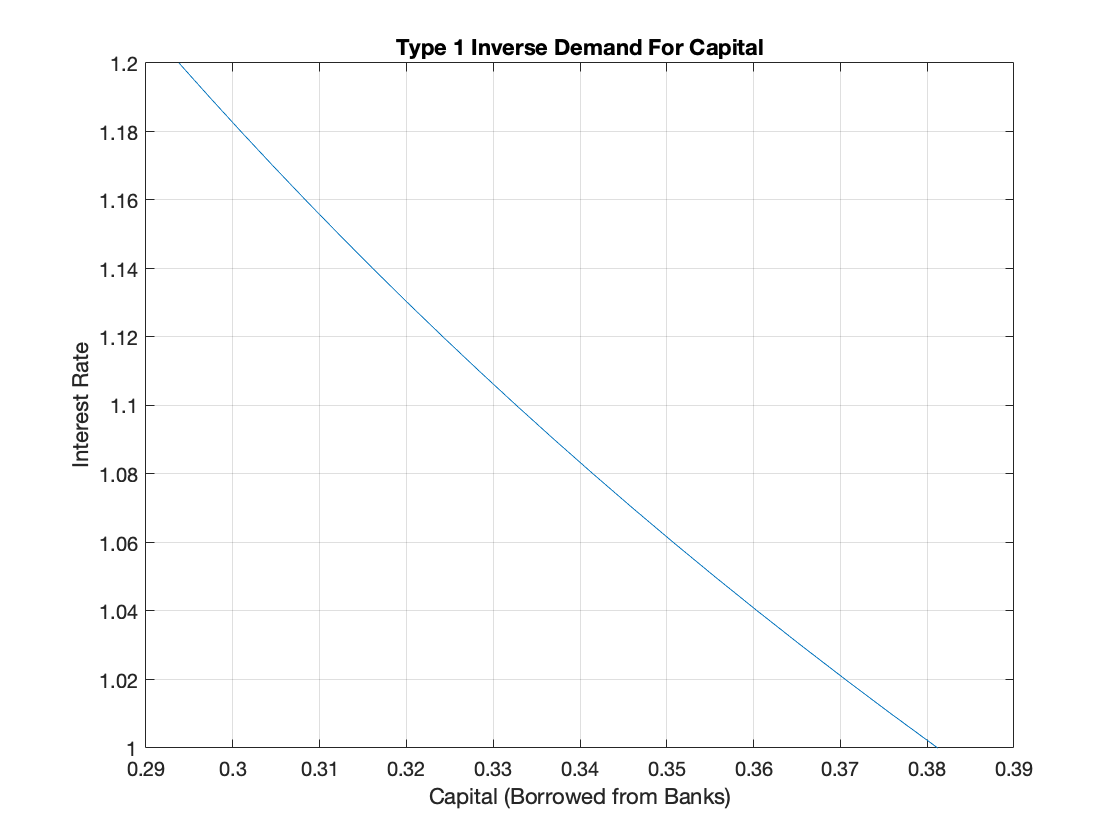

% Parameters for Type 1 
p=1; 
L=2; 
A=1.2; 
alpha=0.30; 
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Type 1 Inverse Demand For Capital'});
grid on;

Demand curve for Type 2 

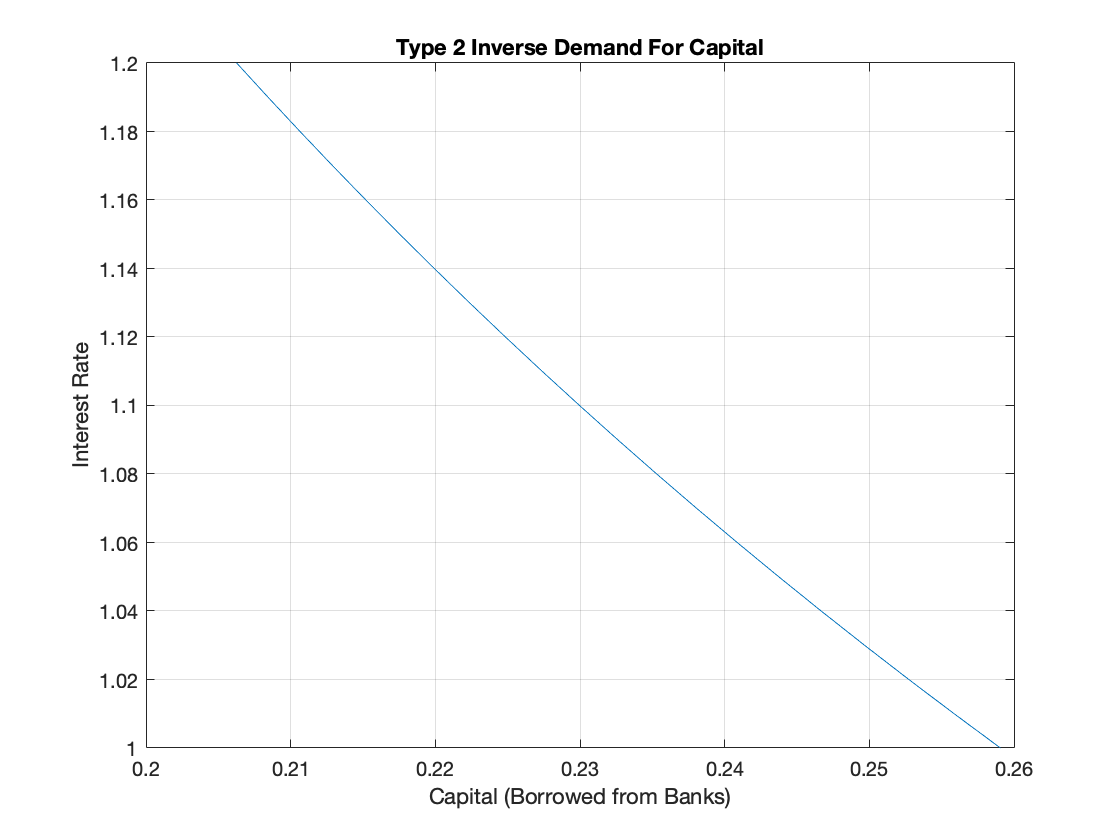

% Parameters for Type 2 
p=1; 
L=2; 
A=1.2; 
alpha=0.20; 
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Type 2 Inverse Demand For Capital'});
grid on;

Demand curve for Type 3 

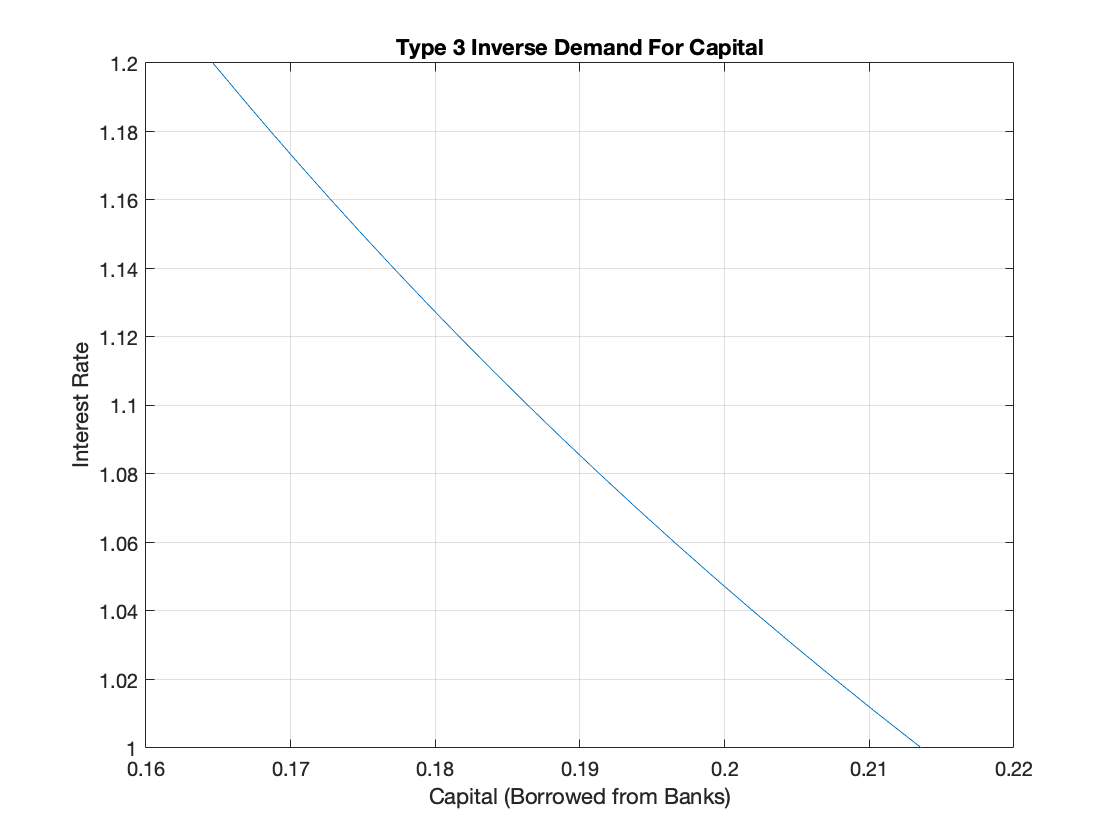

% Parameters for Type 3 
p=1; 
L=2; 
A=0.8; 
alpha=0.30; 
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Type 3 Inverse Demand For Capital'});
grid on;

Demand curve for Type 4

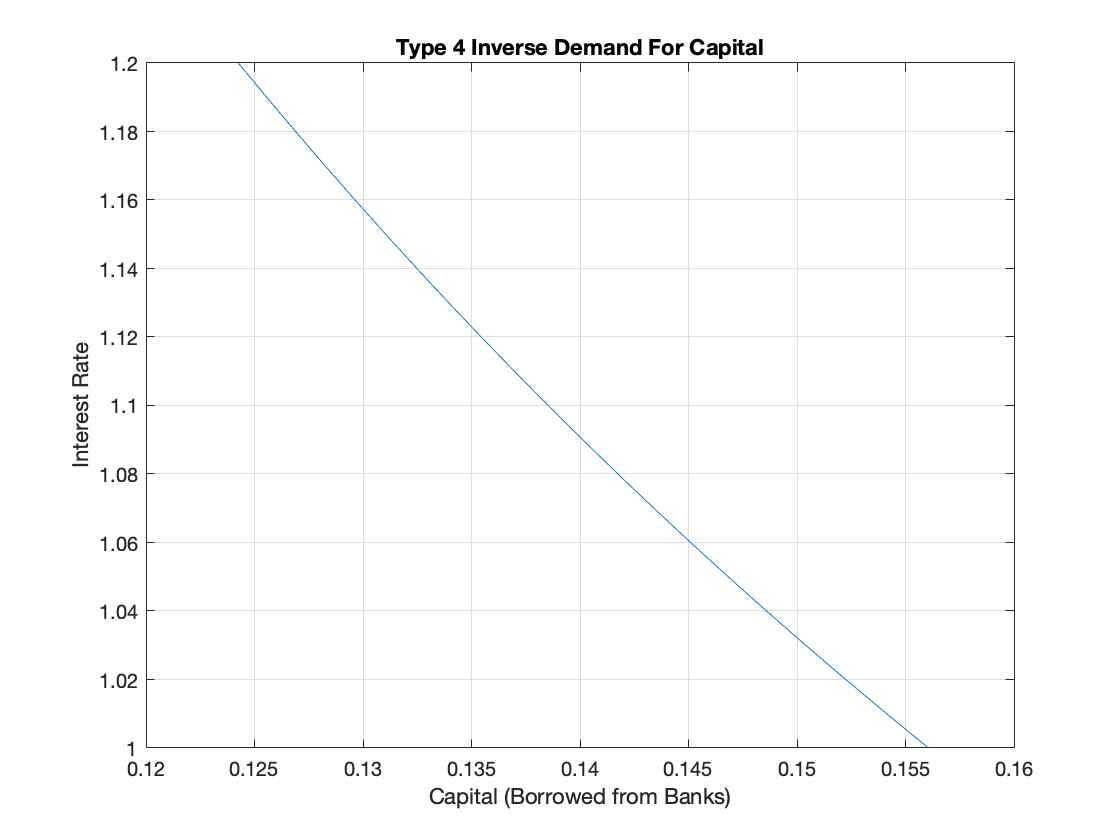

% Parameters for Type 4  
p=1; 
L=2; 
A=0.8; 
alpha=0.20; 
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= (r/(p*A*alpha*(L^0.5))).^(1/(alpha-1));
% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Type 4 Inverse Demand For Capital'});
grid on;

Aggregate Demand (Type1-4 put together in single demand curve)

% Parameters for Aggregate Demand  
p=1; 
L=2; 
A_l=0.8; 
A_h=1.2;
alpha_l=0.20; 
alpha_h=0.30;
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Demand Curve
K= t1*(r/(p*A_h*alpha_h*(L^0.5))).^(1/(alpha_h-1)) + t2*(r/(p*A_h*alpha_l*(L^0.5))).^(1/(alpha_l-1)) + t3*(r/(p*A_l*alpha_h*(L^0.5))).^(1/(alpha_h-1)) + t4*(r/(p*A_l*alpha_l*(L^0.5))).^(1/(alpha_l-1)) 

K =     0.2695    0.2661    0.2627    0.2595    0.2563    0.2531    0.2500    0.2470    0.2441    0.2412    0.2384    0.2356    0.2329    0.2303    0.2277    0.2251    0.2226    0.2202    0.2178    0.2154    0.2131


% Plot
figure();
plot(K,r);
xlabel('Capital (Borrowed from Banks)');
ylabel('Interest Rate');
title({'Aggregate Inverse Demand For Capital'});
grid on;

Aggregate Supply for Capital 

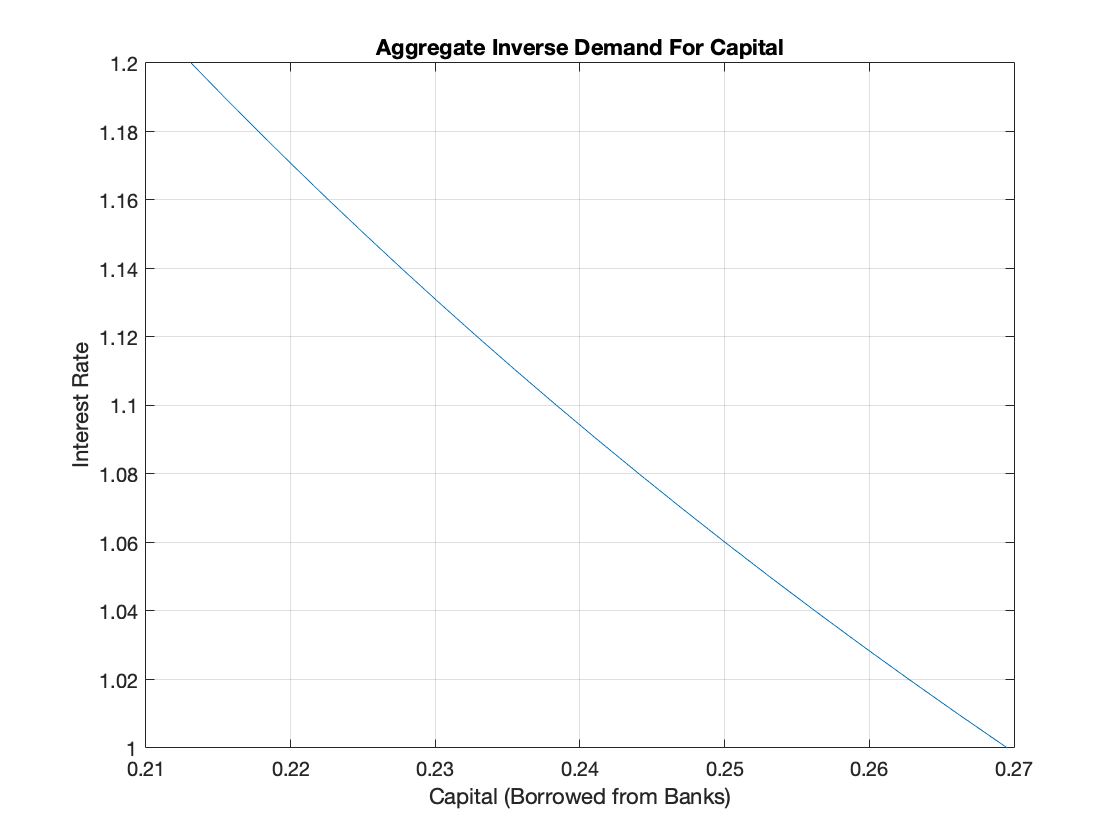

hold on;

t1 = 0.1270

t1 = 0.1270

t2 = 0.7974

t2 = 0.7974

t3 = 0.0478

t3 = 0.0478

t4 = 0.0278

t4 = 0.0278

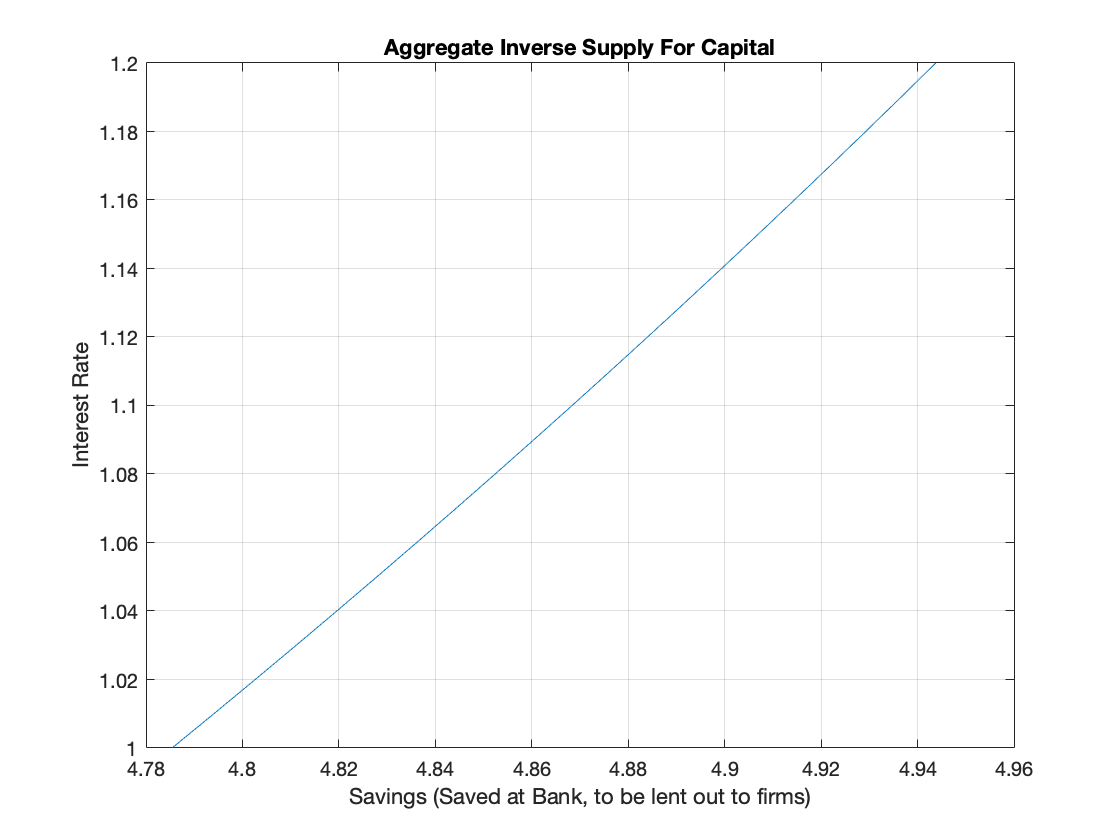

z_l = 10;
z_h = 30;
beta_l = 0.85;
beta_h = 0.95;
grid_points = 21;
% Vector of interest rates
r = linspace(1.0,1.2,grid_points);
% Aggrregate Savings model 
s = t1*[(z_h*beta_h*(1+r)-(z_h/2))./((1+r)*(1+beta_h))] + t2*[(z_l*beta_h*(1+r)-(z_l/2))./((1+r)*(1+beta_h))] + t3*[(z_h*beta_l*(1+r)-(z_h/2))./((1+r)*(1+beta_l))] + t4*[(z_l*beta_l*(1+r)-(z_l/2))./((1+r)*(1+beta_l))];
figure();
plot(s,r);
xlabel('Savings (Saved at Bank, to be lent out to firms)');
ylabel('Interest Rate');
title({'Aggregate Inverse Supply For Capital'});
grid on;
hold off;

**3.4 Elasticity**